clear all
close all
Gv = tf(0.3,[0.03 1])

Gv =
 
     0.3
  ----------
  0.03 s + 1
 
Continuous-time transfer function.



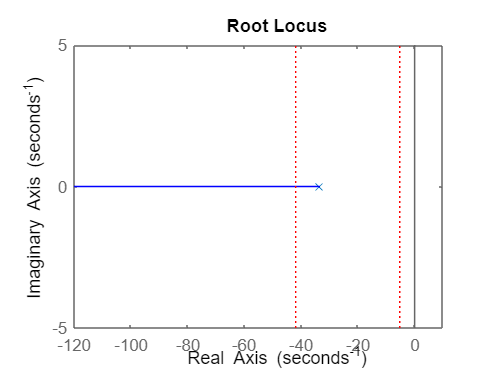

figure('name', ['LDR con CA(s) = K*Gv(s)'])
rlocus(Gv)
hold on
for ts = [0.075 0.6]
    plot([-1 -1]*pi/ts, [-1 1]*5, 'r:')
end
axis([-120 10 -5 5])

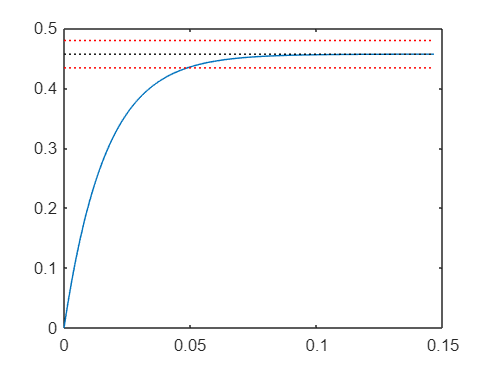

hold off

M =
 
      0.84
  -------------
  0.03 s + 1.84
 
Continuous-time transfer function.



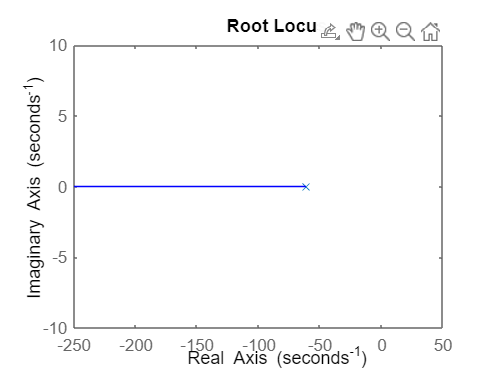

M =
 
      2.25
  -------------
  0.03 s + 3.25
 
Continuous-time transfer function.



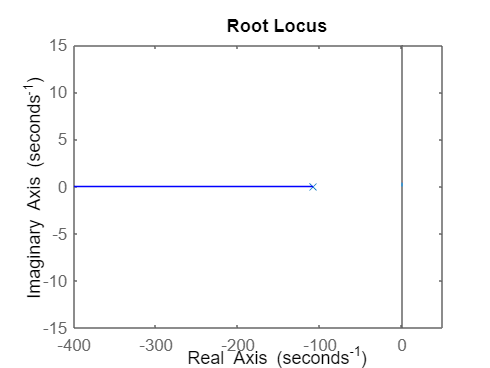

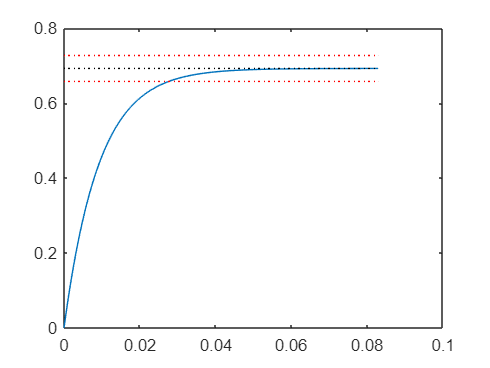

for K = [2.8 7.5];
    M = feedback(K*Gv,1)
    figure('name', ['Respuesta M para K = ' num2str(K)])
    [c,t] = step(M);
    c_inf = c(end);
    plot(t,c)
    hold on
    plot([t(1) t(end)], [1 1]*c_inf,'k:')
    plot([t(1) t(end)], [1 1]*c_inf*0.95,'r:')
    plot([t(1) t(end)], [1 1]*c_inf*1.05,'r:')
end

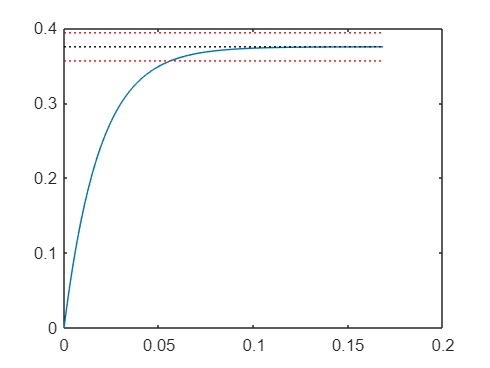

hold off

T = 5e-3;
BGv = c2d(Gv,T,'zoh')

BGv =
 
   0.04606
  ----------
  z - 0.8465
 
Sample time: 0.005 seconds
Discrete-time transfer function.



figure('name', 'LDR con CA(z) = K*BGv(z)')
rlocus(BGv)
hold on
for ts = [0.075 0.6]
    ks = ceil(ts/T)
    UnitCircle(exp(-pi/ks))
end

ks = 15

ks = 120

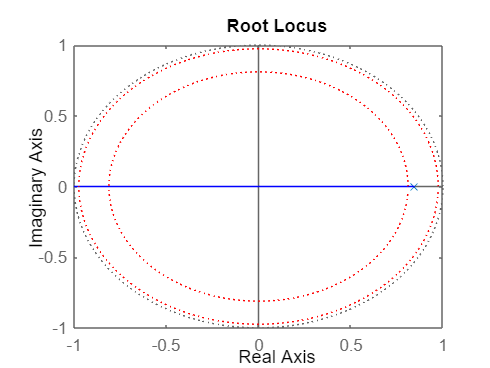

axis([-1 1 -1 1])

M =
 
   0.04606
  ----------
  z - 0.8004
 
Sample time: 0.005 seconds
Discrete-time transfer function.



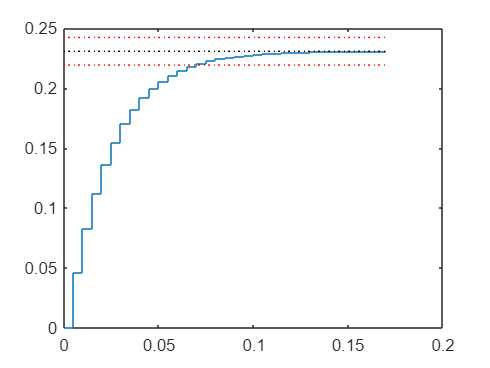

M =
 
   0.09211
  ----------
  z - 0.7544
 
Sample time: 0.005 seconds
Discrete-time transfer function.



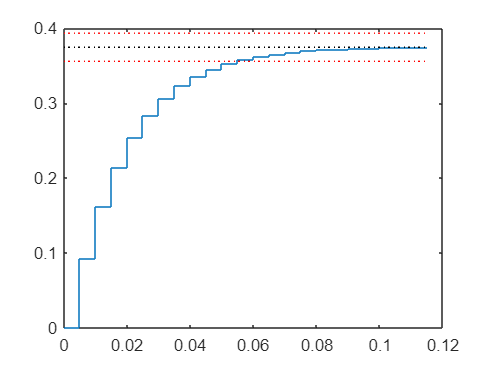

for K = [1 2];
    M = feedback(K*BGv,1)
    figure('name', ['Respuesta M para K=' num2str(K) ' y T=' num2str(T)])
    [c,t] = step(M);
    c_inf = c(end);
    stairs(t,c)
    hold on
    plot([t(1) t(end)], [1 1]*c_inf,'k:')
    plot([t(1) t(end)], [1 1]*c_inf*0.95,'r:')
    plot([t(1) t(end)], [1 1]*c_inf*1.05,'r:')
end

Gp = tf(4,[0.03 1 0])

Gp =
 
       4
  ------------
  0.03 s^2 + s
 
Continuous-time transfer function.



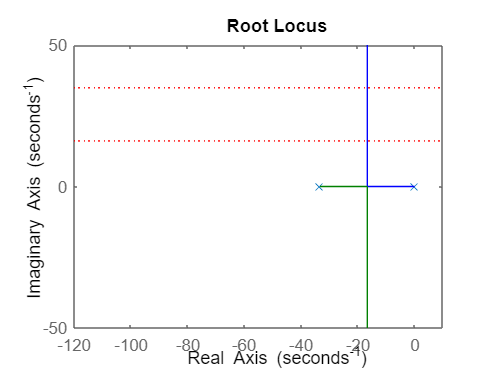

figure('name','LDR con CA(s) = K* Gp(s)')
rlocus(Gp)
hold on
for tp = [0.09 0.195]
    plot([-120 10], [1 1]*pi/tp,'r:')
end
axis([-120 10 -50 50])

T = 5e-3

T = 0.0050

BGp = c2d(Gp,T,'zoh')

BGp =
 
  0.001578 z + 0.001493
  ----------------------
  z^2 - 1.846 z + 0.8465
 
Sample time: 0.005 seconds
Discrete-time transfer function.



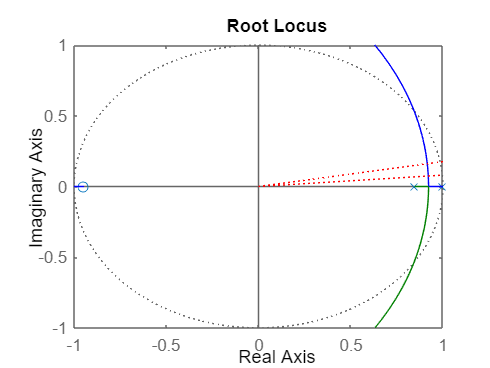

figure('name','LDR con CA(z) = K*BGp(z)')
rlocus(BGp)
hold on
for tp = [0.09 0.195]
    kp = round(tp/T);
    plot([0 1], [0 tan(pi/kp)],'r:')
end
axis([-1 1 -1 1])